clear

path_hazy = 'C:\Users\Administrator\Desktop\Code_available_SLP\hazy images' % the path to hazy examples

path_hazy = 'C:\Users\Administrator\Desktop\Code_available_SLP\hazy images'

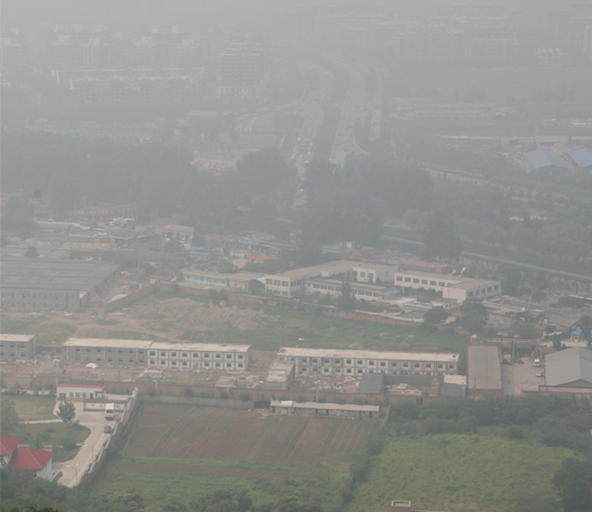

cd(path_hazy) % enter into the file
[filename,pathname] = uigetfile('*.png');

I = imread([pathname,filename]);  
imshow(I,'Border','tight')

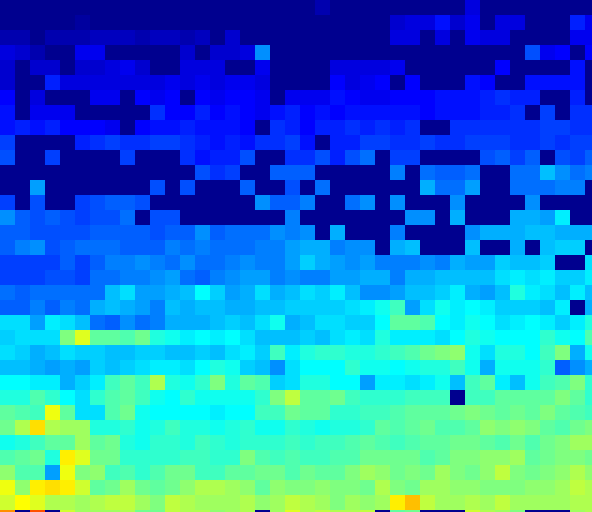


% pre-defined hyper-parameters
patch_size = 15;
number_threshold = 10;
length_threshold = 0.1; % empirically speaking, it is better to be lower when facing dense haze scenes
b0 = 20/255;
b1 = 300/255;
color_failure = [241, 242, 246]; % only for the visualtion of failure regions 

II = double(I)/255;
[m,n,~] = size(II);

% calculate the atmospheric light
A = get_atmospheric_light(II);
AA = reshape(repmat(A,[m*n,1]),m,n,3);

% obtain the saturation value and 
HSV = rgb2hsv(II./AA);
S_Vr = HSV(:,:,2:3);
S_Vr(:,:,2) = 1./(S_Vr(:,:,2)+eps); % avoid the case with zero as denominator  

% define the function using non-overlapping patches
fun = @(block_struct)get_transmission(block_struct.data,number_threshold,length_threshold);

% calculate transmission map for the first time
t_crop_1 = blockproc(S_Vr,[patch_size,patch_size],fun);

% visualizaion
imshow(t_crop_1,'Border','tight')
colormap('jet')
F = getframe(gcf);

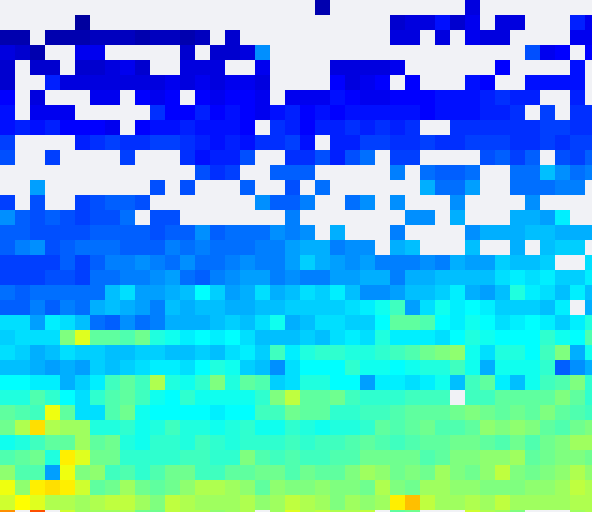

t_crop_1_show = imresize(F.cdata,size(I,1)/size(F.cdata,1));
for k=1:3
    data_medium = t_crop_1_show(:,:,k);
    data_medium(t_crop_1==0) = color_failure(k);
    t_crop_1_show(:,:,k) = data_medium;
end 
imshow(t_crop_1_show,'Border','tight')

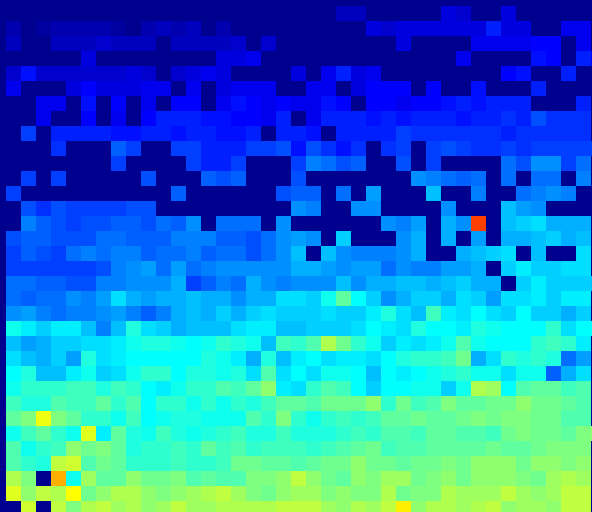


% calculate the transmission map for the scecond time 
patch_mid = floor(patch_size/2);
t_crop_2 = blockproc(S_Vr(patch_mid:m,patch_mid:n,:),[patch_size,patch_size],fun);
t_crop_2 = [zeros(patch_mid-1,n);[zeros(m-patch_mid+1,patch_mid-1),t_crop_2]];

% visualization
imshow(t_crop_2,'Border','tight')
colormap('jet')
F=getframe(gcf);

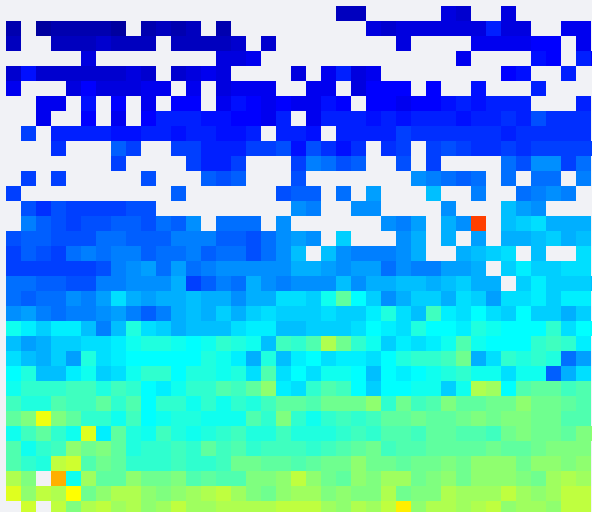

t_crop_2_show = imresize(F.cdata,size(I,1)/size(F.cdata,1));
for k=1:3
    data_medium = t_crop_2_show(:,:,k);
    data_medium(t_crop_2==0) = color_failure(k);
    t_crop_2_show(:,:,k) = data_medium;
end 
imshow(t_crop_2_show,'Border','tight')

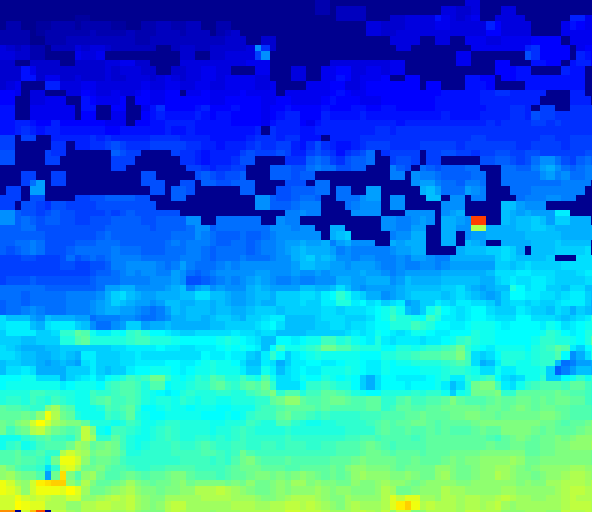


% calculate the mean value of transmission map
number = (t_crop_1>0)+(t_crop_2>0);
t_mean = (t_crop_1+t_crop_2)./number;

transmission = zeros(m,n);
transmission(t_mean>0) = t_mean(t_mean>0);

% visualization
imshow(transmission,'Border','tight')
colormap('jet')
F = getframe(gcf);

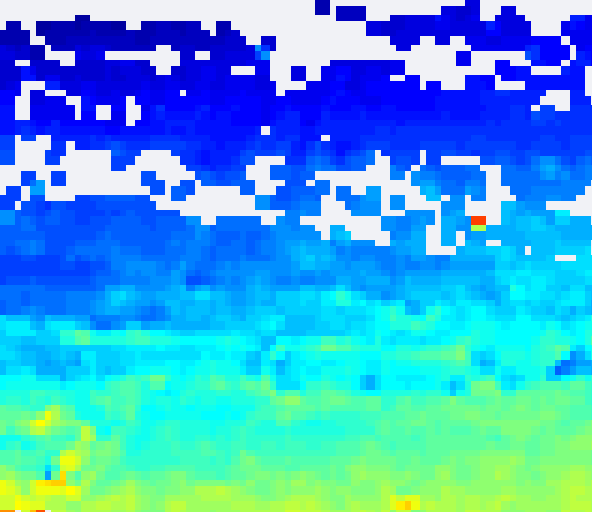

t_mean_show = imresize(F.cdata,size(I,1)/size(F.cdata,1));
for k=1:3
    data_medium = t_mean_show(:,:,k);
    data_medium(number==0) = color_failure(k);
    t_mean_show(:,:,k) = data_medium;
end
imshow(t_mean_show,'Border','tight')

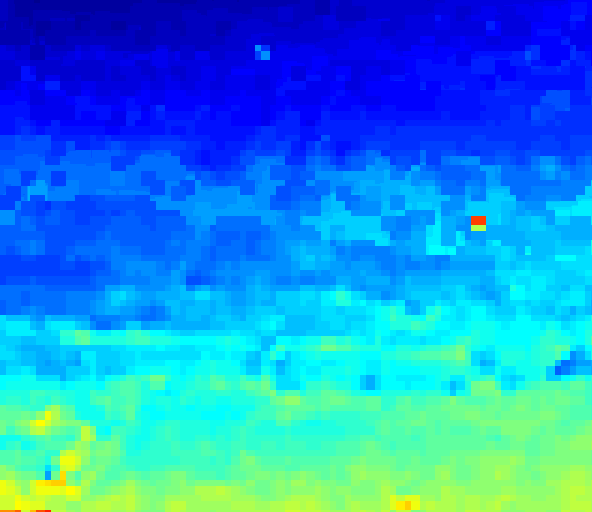


% combine with boundary constraints
t_f = transmission;
t_boundary = max(max((II-AA)./(b1-AA),(II-AA)./(b0-AA)),[],3);
t_boundary = maxfilt2(t_boundary,patch_size);
t_f(number==0) = t_boundary(number==0);

% visualization
imshow(t_f,'Border','tight')
colormap('jet')

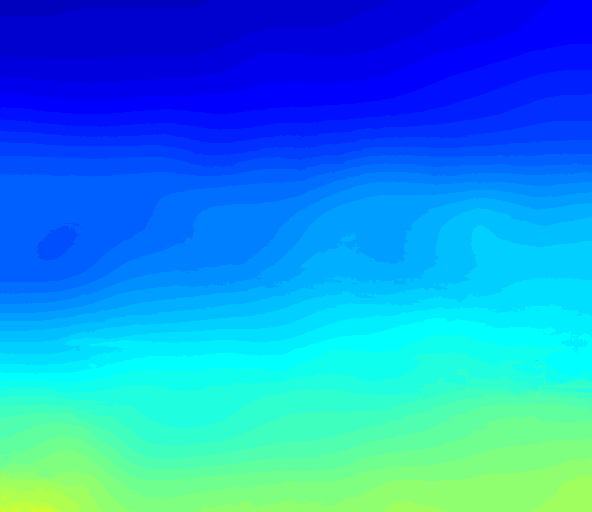


% refine the transmission map using minimal transmission threshold
t_sl = reshape(transmission(transmission>0),1,[]);
t_l = prctile(t_sl,5);
t_min = mean(t_sl(t_sl<t_l));
t_r = min(max(t_f,t_min),1);

% refine the transmission using guided filter
t_final = guidedfilter(rgb2gray(II),t_r,2*patch_size,0.01); % non-overlapping patches calls for larger patch size in smoothing

% visualization
imshow(t_final,'Border','tight')
colormap('jet')

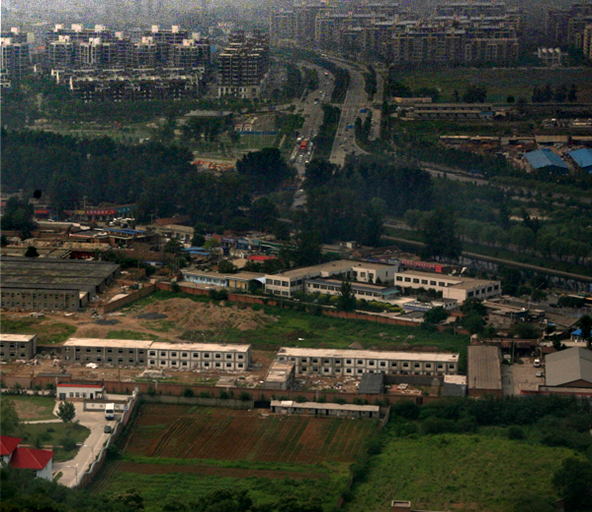


% ontain the dehazing results using atmospheric scattering model
dehaze = ones(size(II));
for k=1:3
dehaze(:,:,k) = (II(:,:,k)-AA(:,:,k))./t_final+AA(:,:,k);
end

imshow(dehaze,'Border','tight')

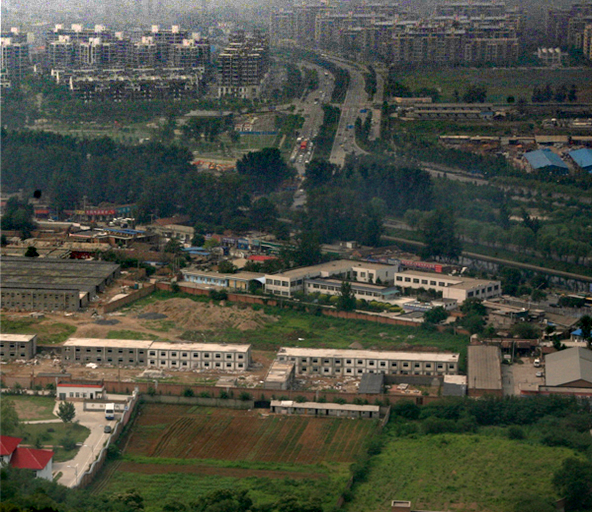


imshow(dehaze.^0.8,'Border','tight') % for Fig. 10 in the paper